# Trabajo Práctico 2: Ejercicio 1

clc; clear; close all;

s = tf('s');
J = 0.12; %Nms^2/rad
b = 0.09; %Nms/rad
Gc = tf(1);
Km = 1;
Gla = Km/(J*s + b) * (1/s) % Ganancia de la planta

Gla =
 
          1
  -----------------
  0.12 s^2 + 0.09 s
 
Continuous-time transfer function.
Model Properties


Glc = feedback(Gc * Gla, 1) % Sistema en lazo cerrado con compensador unitario

Glc =
 
            1
  ---------------------
  0.12 s^2 + 0.09 s + 1
 
Continuous-time transfer function.
Model Properties


## Punto A

### Tipo de Sistema

La FTLA es un sistema de tipo 1, ya que tiene un polo en el origen a lazo abierto.

### Error de Posición


$$e_{ssp} = \lim_{s\to 0} sE(s) = \lim_{s\to 0} \frac{s}{1+G_{la}(s)} \frac{1}{s} = \frac{1}{1+G_{la}(0)}$$



$$e_{ssp} = \lim_{s\to 0} \frac{1}{1+ \frac{K_m}{s(Js+b)}} = 0$$


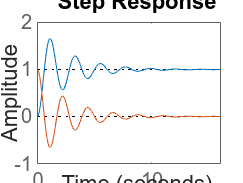

E = 1/(1 + Gla);
step(Glc, E)

### Error de Velocidad


$$e_{ssv} = \lim_{s\to 0} s E(s) = \lim_{s\to 0} \frac{s}{1+G_{la}(s)}\frac{1}{s^2}$$



$$e_{ssv} = \lim_{s\to 0} \frac{1}{s ( 1 + G_{la}(s))} = \lim_{s\to 0} \frac{1}{s + sG_{la}(s)}$$



$$e_{ssv} = \lim_{s\to 0} \frac{1}{s + s \cdot \frac{K_m}{s(Js+b)}}$$



$$e_{ssv} = \lim_{s\to 0} \frac{1}{s + \frac{K_m}{Js+b}} = \frac{1}{0 + \frac{K_m}{b}}$$



$$e_{ssv} = \frac{b}{K_m} \equiv ctte.$$


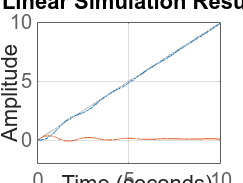

t = linspace(0, 10, 10000);
r = t;
lsim(Glc, r, t); hold on
lsim(E, r, t); hold off
grid on

### Error de Aceleración


$$e_{ssa} = \lim_{s\to 0} s E(s) = \lim_{s\to 0} \frac{s}{1 + G_{la}(s)} \frac{1}{s^3}$$



$$e_{ssa} = \lim_{s\to 0} \frac{1}{s^2 (1 + G_{la}(s))} = \frac{1}{s^2 + s^2 \cdot G_{la}(s)}$$



$$e_{ssa} = \lim_{s\to 0} \frac{1}{s^2 + s^2 \cdot \frac{K_m}{s(Js+b)}} = \lim_{s\to 0} \frac{1}{s^2 + \frac{s \cdot K_m}{Js+b}} = \frac{1}{0} = \infty$$


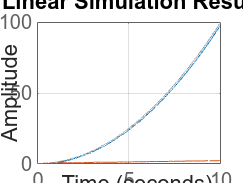

q = t.^2;
lsim(Glc, q, t); hold on
lsim(E, q, t); hold off
grid on

## Punto B

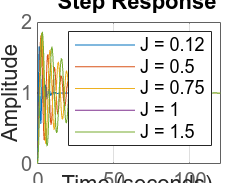

Gla1 = Km/(0.12*s + b) * (1/s);
Glc1 = feedback(Gla1, 1);
Gla2 = Km/(0.5*s + b) * (1/s);
Glc2 = feedback(Gla2, 1);
Gla3 = Km/(0.75*s + b) * (1/s);
Glc3 = feedback(Gla3, 1);
Gla4 = Km/(1*s + b) * (1/s);
Glc4 = feedback(Gla4, 1);
Gla5 = Km/(1.5*s + b) * (1/s);
Glc5 = feedback(Gla4, 1);
step(Glc1, Glc2, Glc3, Glc4, Glc5)
grid on
legend('J = 0.12', 'J = 0.5', 'J = 0.75', 'J = 1', 'J = 1.5')

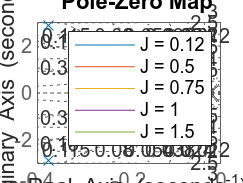

pzplot(Glc1, Glc2, Glc3, Glc4, Glc5)
grid on
legend('J = 0.12', 'J = 0.5', 'J = 0.75', 'J = 1', 'J = 1.5')

info = [stepinfo(Glc1);
        stepinfo(Glc2);
        stepinfo(Glc3);
        stepinfo(Glc4);
        stepinfo(Glc5)]

info = 5×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


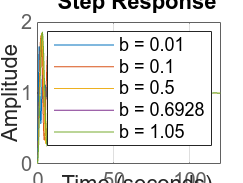

Gla6 = Km/(J*s + 0.01) * (1/s);
Glc6 = feedback(Gla1, 1);
Gla7 = Km/(J*s + 0.1) * (1/s);
Glc7 = feedback(Gla2, 1);
Gla8 = Km/(J*s + 0.5) * (1/s);
Glc8 = feedback(Gla3, 1);
Gla9 = Km/(J*s + 0.6928) * (1/s);
Glc9 = feedback(Gla4, 1);
Gla10 = Km/(J*s + 1.05) * (1/s);
Glc10 = feedback(Gla4, 1);
step(Glc1, Glc2, Glc3, Glc4, Glc5)
grid on
legend('b = 0.01', 'b = 0.1', 'b = 0.5', 'b = 0.6928', 'b = 1.05')

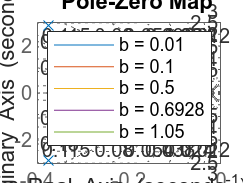

pzplot(Glc1, Glc2, Glc3, Glc4, Glc5)
grid on
legend('b = 0.01', 'b = 0.1', 'b = 0.5', 'b = 0.6928', 'b = 1.05')

info2 = [stepinfo(Glc6);
        stepinfo(Glc7);
        stepinfo(Glc8);
        stepinfo(Glc9);
        stepinfo(Glc10)]

info2 = 5×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


## Punto C

## Controlador Proporcional

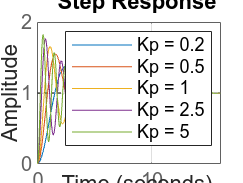

J = 0.12;
b = 0.09;
Gla = 1/(s*(J*s+b));
Gc1 = 0.2;
Glc1 = feedback(Gc1 * Gla, 1);
Gc2 = 0.5;
Glc2 = feedback(Gc2 * Gla, 1);
Gc3 = 1;
Glc3 = feedback(Gc3 * Gla, 1);
Gc4 = 2.5;
Glc4 = feedback(Gc4 * Gla, 1);
Gc5 = 5;
Glc5 = feedback(Gc5 * Gla, 1);
step(Glc1, Glc2, Glc3, Glc4, Glc5)
grid on
legend('Kp = 0.2', 'Kp = 0.5', 'Kp = 1', 'Kp = 2.5', 'Kp = 5')

### Controlador Integral

No es necesario, ya que la planta tiene un TF de tipo 1 y sigue el escalón con error nulo.

### Controlador Derivativo

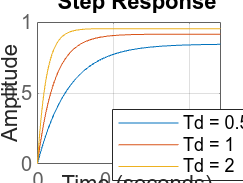

J = 0.12;
b = 0.09;
Gla = 1/(s*(J*s+b));
Gc1 = 0.5*s;
Glc1 = feedback(Gc1 * Gla, 1);
Gc2 = 1*s;
Glc2 = feedback(Gc2 * Gla, 1);
Gc3 = 2*s;
Glc3 = feedback(Gc3 * Gla, 1);
step(Glc1, Glc2, Glc3)
grid on
legend('Td = 0.5', 'Td = 1', 'Td = 2')

#### Controlador Proporcional-Derivativo

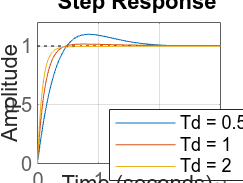

J = 0.12;
b = 0.09;
Gla = 1/(s*(J*s+b));
Gc1 = 1 * (1 + 0.5*s);
Glc1 = feedback(Gc1 * Gla, 1);
Gc2 = 1 * (1 + 1*s);
Glc2 = feedback(Gc2 * Gla, 1);
Gc3 = 1 * (1 + 1.5*s);
Glc3 = feedback(Gc3 * Gla, 1);
step(Glc1, Glc2, Glc3)
grid on
legend('Td = 0.5', 'Td = 1', 'Td = 2')